clear
close all

## PN Sequence

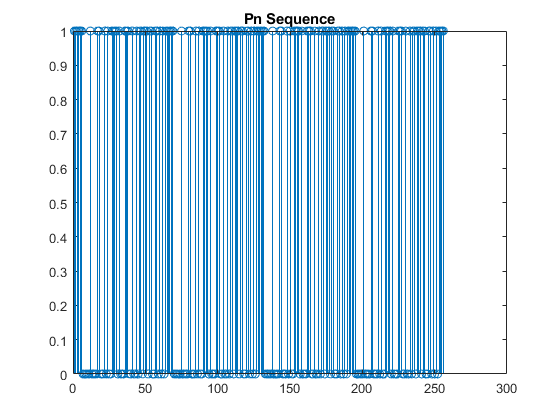

N = 256;

pn_generator = comm.PNSequence("InitialConditions",[1 1 1 1 1 1], "Polynomial", [1 0 0 0 0 1 1], "SamplesPerFrame", N);
pn_sequence = pn_generator()';

figure(1)
stem(pn_sequence)
title("Pn Sequence")


pn_sequence = [0 0 pn_sequence];
pn_sequence = [pn_sequence];

## Convolutional Code

### Generator Polynomials

g1 = [1 0];
g2 = [1 1];
g3 = [0 1];

o1 = bitxor(g1(1) * pn_sequence(2: N + 2), g1(2) * pn_sequence(1:N + 1));
o2 = bitxor(g2(1) * pn_sequence(2: N + 2), g2(2) * pn_sequence(1:N + 1));
o3 = bitxor(g3(1) * pn_sequence(2: N + 2), g3(2) * pn_sequence(1:N + 1));

### Generate Code

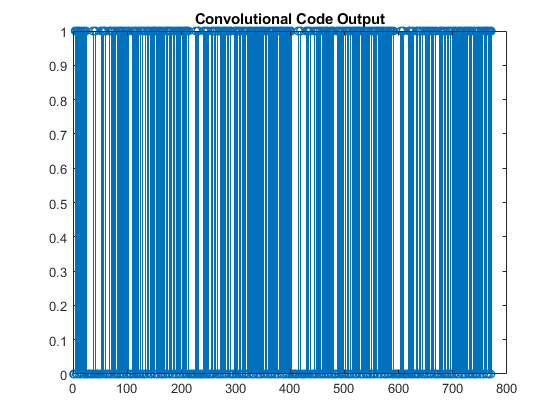

Output = [o3; o2; o1];
Output = flip(Output, 2);
Output = reshape(Output, [1 (N + 1)*3]);
Output = Output((N + 1) * 3:-1:1);

figure(2)
stem(Output)
title("Convolutional Code Output")

## Decoding

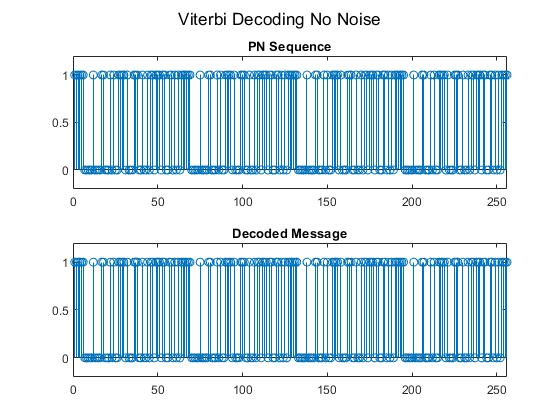

message = ViterbiDecode(Output, N);

figure(3)
subplot(2, 1, 1)
stem(pn_sequence(3:N + 2))

xlim([0.0 N])
ylim([-0.2 1.20])
title("PN Sequence")
subplot(2, 1, 2)
stem(message)

xlim([0.0 N])
ylim([-0.2 1.20])
title("Decoded Message")
sgtitle("Viterbi Decoding No Noise")


sprintf("Match %% = %3.2f", 100 * sum(pn_sequence(3:N+2) == message)/N)

ans = "Match % = 100.00"

## Channels

### Binary Symmetric Channel

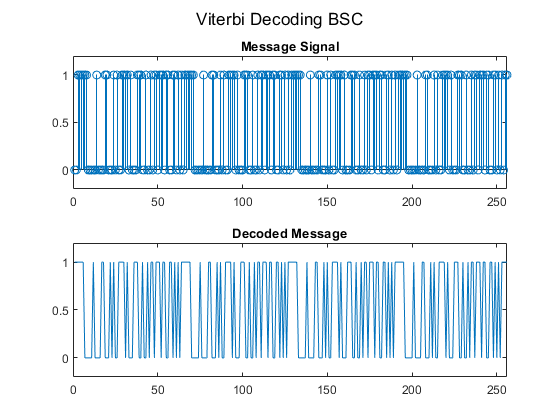

p = 1 /8;

BSC_Output= BSC(Output, p);

message = ViterbiDecode(Output, N);

figure(5)
subplot(2, 1, 1)
stem(pn_sequence)

xlim([0.0 N])
ylim([-0.2 1.20])
title("Message Signal")
subplot(2, 1, 2)
plot(message)

xlim([0.0 N])
ylim([-0.2 1.20])
title("Decoded Message")
sgtitle("Viterbi Decoding BSC")


sprintf("BSC Match %% = %3.2f", 100 * sum(pn_sequence(3:N+2) == message)/N)

ans = "BSC Match % = 100.00"

### Binary Asymmetric Channel

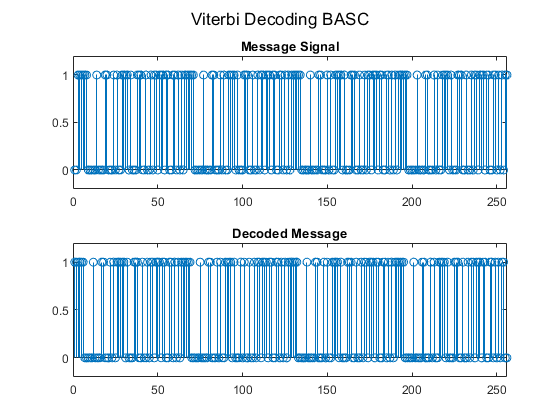

p1 = 1 /8;
p2 = 1 /22;

BASC_Output = BASC(Output, p1, p2);
message = ViterbiDecode(BASC_Output, N, 1, p1, p2);

figure(7)
subplot(2, 1, 1)
stem(pn_sequence)
xlim([0.0 N])
ylim([-0.2 1.20])
title("Message Signal")
subplot(2, 1, 2)
stem(message)
xlim([0.0 N])
ylim([-0.2 1.20])
title("Decoded Message")
sgtitle("Viterbi Decoding BASC")


sprintf("BASC Match %% = %3.2f", 100 * sum(pn_sequence(3:N+2) == message)/N)

ans = "BASC Match % = 98.44"

## BER Plots for BSC

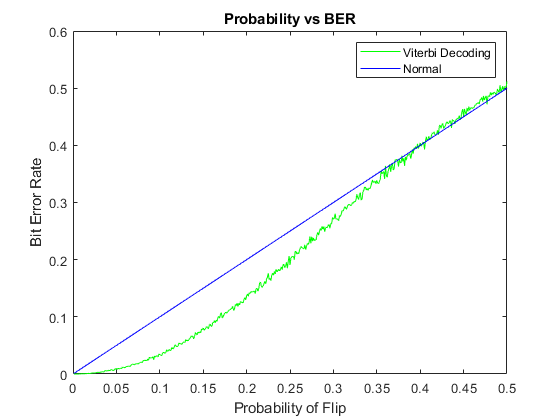

num_repeatations = 50;

ps = linspace(0.5, 0.001, 500);
BERs = zeros(size(ps));

for i=1:length(ps)
    p = ps(i);
    
    for j=1:num_repeatations
        BSC_Output = BSC(Output, p);
        
        message = ViterbiDecode(BSC_Output, N);

        BERs(i) = BERs(i) + 1 - mean(pn_sequence(3:N+2) == message);
    end
    BERs(i) = BERs(i) / num_repeatations;
end

figure(8)
plot(ps, BERs, 'green')
title("Probability vs BER")
xlabel("Probability of Flip")
ylabel("Bit Error Rate")
line([ps(1) ps(length(ps))], [ps(1) ps(length(ps))], 'Color','blue')
legend("Viterbi Decoding", "Normal")

## BER Plots for BAC

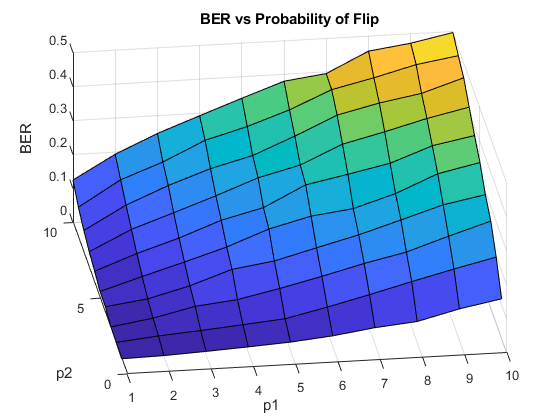

num_repeatations = 20;

p1s = linspace(0.01, 0.5, 10);
p2s = linspace(0.01, 0.5, 10);
BERs = zeros(length(p1s), length(p2s));

for i=1:length(p1s)
    for j=1:length(p2s)
        p1 = p1s(i);
        p2 = p2s(j);
        for k=1:num_repeatations
            BASC_Output = BASC(Output, p1, p2);
            
            message = ViterbiDecode(BASC_Output, N, 1, p1, p2, 1);
    
            BERs(i, j) = BERs(i, j) + 1 - mean(pn_sequence(3:N+2) == message);
        end
        BERs(i, j) = BERs(i, j) / num_repeatations;
    end
end

figure(8)
surf(BERs)
title("BER vs Probability of Flip")
xlabel("p1")
ylabel("p2")
zlabel("BER")

## Argument in Lab about using log on weigths

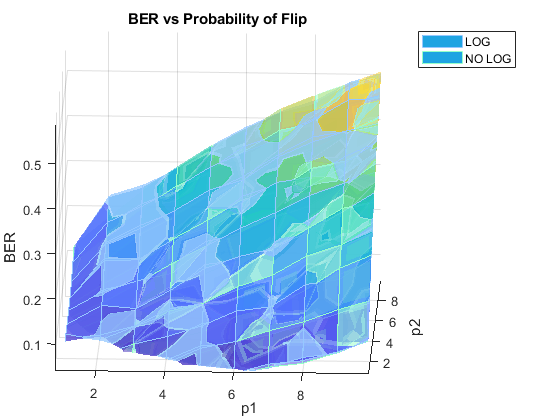

BERs_no_log = zeros(length(p1s), length(p2s));

for i=1:length(p1s)
    for j=1:length(p2s)
        p1 = p1s(i);
        p2 = p2s(j);
        for k=1:num_repeatations
            BASC_Output = BASC(Output, p1, p2);
            
            message = ViterbiDecode(BASC_Output, N, 1, p1, p2, 0);
    
            BERs_no_log(i, j) = BERs_no_log(i, j) + 1 - mean(pn_sequence(3:N+2) == message);
        end
        BERs_no_log(i, j) = BERs_no_log(i, j) / num_repeatations;
    end
end

figure(9)
hold on
surf(BERs, 'EdgeColor', [150/255 255/255 200/255], 'FaceColor', [150/255 255/255 200/255], 'FaceAlpha', 0.5)
surf(BERs_no_log, 'EdgeColor', [150/255 200/255 255/255], 'FaceColor', [150/255 200/255 255/255], 'FaceAlpha', 0.75)
title("BER vs Probability of Flip")
xlabel("p1")
ylabel("p2")
zlabel("BER")
legend("LOG", "NO LOG")
view(17,22)
hold off

## Functions

function perturbed_sequence = BSC(sequence, p)
    l = length(sequence);
    distribution = makedist('Binomial', 'N', 1, 'p', p);
    perturbation = random(distribution, l, 1)';
    perturbed_sequence = xor(perturbation, sequence);
end

function perturbed_sequence = BASC(sequence, p1, p2)
    l = length(sequence);

    distribution1 = makedist('Binomial', 'N', 1, 'p', p1);
    distribution2 = makedist('Binomial', 'N', 1, 'p', p2);

    perturbed_sequence = sequence;
    for i=1:l
        if perturbed_sequence(i) == 1
            perturbed_sequence(i) = xor(perturbed_sequence(i), random(distribution2));
        else
            perturbed_sequence(i) = xor(perturbed_sequence(i), random(distribution1));
        end
    end
end

function message = ViterbiDecode(Output, end_after, mode, p1, p2, use_log)
    if nargin < 3
        p1 = 0;
        p2 = 0;
        mode = 0;
        use_log = 1;
    end


    message = zeros([1 end_after+1]);
    transition_matrix = zeros([4 4 4]);

    transition_matrix(1, 1, :) = [0 0 0 0];
    transition_matrix(1, 2, :) = [2 0 0 0];
    transition_matrix(1, 3, :) = [1 1 1 0];
    transition_matrix(1, 4, :) = [2 0 0 0];

    transition_matrix(2, 1, :) = [0 0 0 0];
    transition_matrix(2, 2, :) = [2 0 0 0];
    transition_matrix(2, 3, :) = [1 1 1 0];
    transition_matrix(2, 4, :) = [2 0 0 0];

    transition_matrix(3, 1, :) = [2 0 0 0];
    transition_matrix(3, 2, :) = [0 0 1 1];
    transition_matrix(3, 3, :) = [2 0 0 0];
    transition_matrix(3, 4, :) = [1 1 0 1];

    transition_matrix(4, 1, :) = [2 0 0 0];
    transition_matrix(4, 2, :) = [0 0 1 1];
    transition_matrix(4, 3, :) = [2 0 0 0];
    transition_matrix(4, 4, :) = [1 1 0 1];

    
    path_ = 5 * ones([4 end_after+2 2]);

    path_(1, 1, 1) = 1;
    path_(1, 1, 2) = 0;
    
    for i=1:end_after + 1
        o_1 = Output(3 * i -2);
        o_2 = Output(3 * i -1);
        o_3 = Output(3 * i   );
        
        for j=1:4
            if path_(j, i, 1) < 5
                for k=1:4
                    if transition_matrix(j, k, 1) < 2
                        o_expected_1 = transition_matrix(j, k, 2);
                        o_expected_2 = transition_matrix(j, k, 3);
                        o_expected_3 = transition_matrix(j, k, 4);

                        hamming_distance = xor(o_expected_1, o_1) + xor(o_expected_2, o_2) + xor(o_expected_3, o_3);
                        
                        linear_distance = (o_expected_1 / p2 + (1 - o_expected_1) / p1) * xor(o_expected_1, o_1) + (o_expected_2 / p2 + (1 - o_expected_2) / p1) * xor(o_expected_2, o_2) + (o_expected_3 / p2 + (1 - o_expected_3) / p1) * xor(o_expected_3, o_3);
                        
                        sigmoid_distance = (o_expected_1 / (1 + exp(p2)) + (1 - o_expected_1) / (1 + exp(p1))) * xor(o_expected_1, o_1) + (o_expected_2 / (1 + exp(p2)) + (1 - o_expected_2) / (1 + exp(p1))) * xor(o_expected_2, o_2) + (o_expected_3 / (1 + exp(p2)) + (1 - o_expected_3) / (1 + exp(p1))) * xor(o_expected_3, o_3);
                        
                        if mode == 0
                            if use_log
                                distance = log(1 + hamming_distance);
                            else
                                distance = hamming_distance;
                            end
                        elseif mode == 1
                            if use_log
                                distance = log(1 + linear_distance);
                            else
                                distance = linear_distance;
                            end
                        elseif mode == 2
                            if use_log
                                distance = log(1 + sigmoid_distance);
                            else
                                distance = sigmoid_distance;
                            end
                        end
                        
                        if path_(k, i+1, 1) < 5
                            if path_(k, i+1, 2) > (path_(j, i, 2) + distance)
                                path_(k, i+1, 1) = j;
                                path_(k, i+1, 2) = path_(j, i, 2) + distance;
                            end
                        else
                            path_(k, i+1, 1) = j;
                            path_(k, i+1, 2) = path_(j, i, 2) + distance;
                        end
                    end
                end
            end
        end
    end

    [~, X] = min(path_(:, end_after + 2, 2));
    for i=end_after+1:-1:2
        message(i) = transition_matrix(path_(X, i + 1, 1), X, 1);
        X = path_(X, i + 1, 1);
    end
    
    message = message(2:end_after + 1);
end